# Analyzing scRNASeq metabolic models

Author: Scott Campit

## Summary

## Load data

clear all
load ~/Analysis/EMT/scRNASeq_indiv_flux.mat;

Get time point labels (columns in the scRxnFx variable)

timepoints = readcell('~/Analysis/EMT/timepoints.txt');
timepoints = string(timepoints);

rm_cells = find(contains(timepoints, 'rm'));
timepoints(rm_cells) = [];

Remove all reactions that contain only zero values.

rm_rxns = all(scRxnFx==0, 2);
data = scRxnFx;
data(rm_rxns, :) = [];
data(:, rm_cells) = [];

Remove identifiers corresponding to reactions with all 0 flux values.

ids = [recon1.rxns, recon1.rxnNames, recon1.subSystems];
ids(rm_rxns, :) = [];

[sorted, idx] = sort(timepoints);
data = data(:, idx);

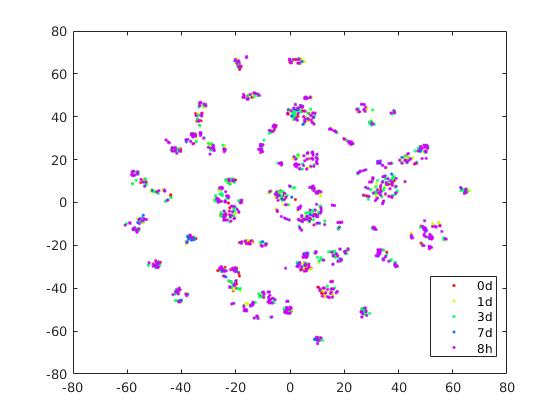

y = tsne(data');
gscatter(y(:, 1), y(:, 2), sorted)

avg_effect = mean(abs(data), 2)

avg_effect =     0.0016
    0.0003
    0.0000
    0.0396
    0.1663
    0.0559
    0.0559
    0.0042
    0.0003
    0.0886


all_data = [avg_effect, data];

[all_data, idx] = sortrows(all_data, 1, 'descend');
ids = ids(idx, :);
data = data(idx, :);

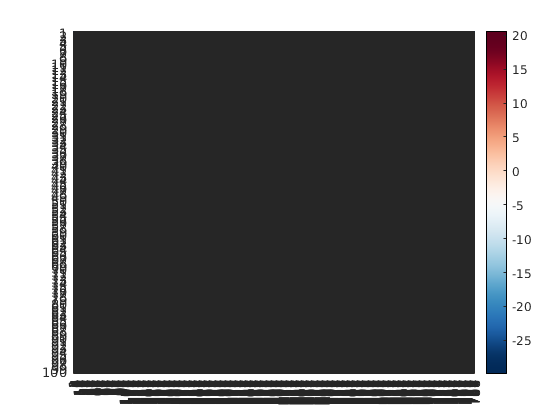

redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);
heatmap(data(1:100, 578:1365), ...
    'Colormap', redbluecmap)

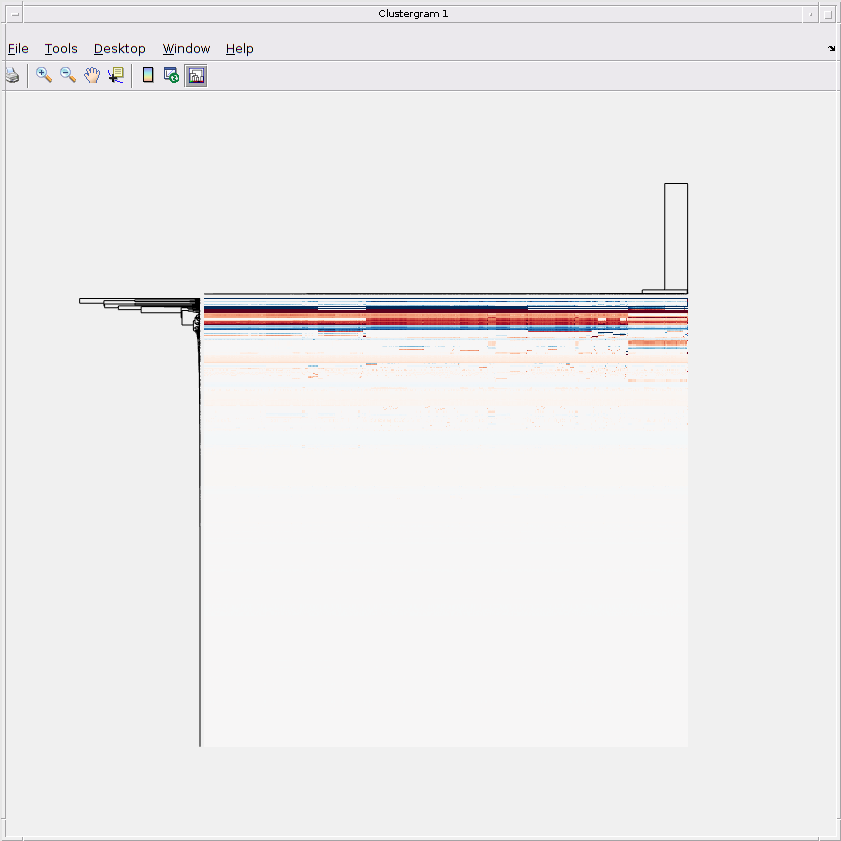

Clustergram object with 941 rows of nodes and 3134 columns of nodes.



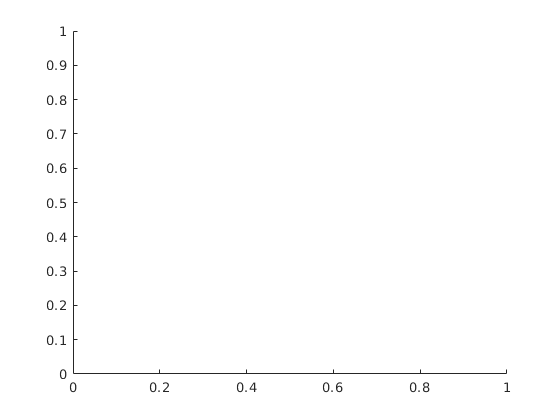

Error using gscatter (line 121)
There must be one value of G for each row of X.

clustergram(data, ...
    'Colormap', redbluecmap)

hr0 = mean(data(:, sorted == '0d'), 2);
hr8 = mean(data(:, sorted == '8h'), 2);
day1 = mean(data(:, sorted == '1d'), 2);
day3 = mean(data(:, sorted == '3d'), 2);
day7 = mean(data(:, sorted == '7d'), 2);

median_data = [hr0, hr8, day1, day3, day7];